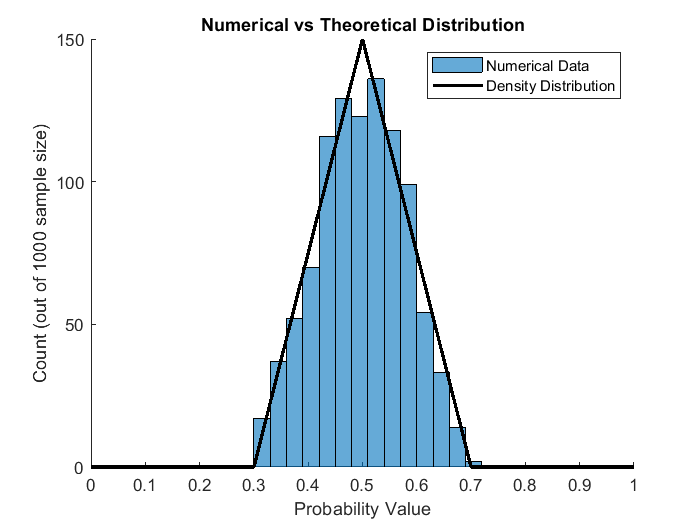

money_density_option = 4;

if money_density_option == 1
    center = 1/2;
    spread = 1/20;
    money_density = @(p) double_stunted_gaussian(p,center,spread);
    gamma = @(p) double_stunted_gaussian_gamma(p,center,spread);
    inv_gamma = @(percentile) double_stunted_gaussian_inverse_gamma(percentile,center,spread);
    % With x = 2
    % Traditional: .0311
    % Outside In P2P: .0350
    % Split n Match P2P: .0342
elseif money_density_option == 2
    center = 3/4;
    spread = 1/20;
    money_density = @(p) double_stunted_gaussian(p,center,spread);
    gamma = @(p) double_stunted_gaussian_gamma(p,center,spread);
    inv_gamma = @(percentile) double_stunted_gaussian_inverse_gamma(percentile,center,spread);
    % With x = 2
    % Traditional: .0335
    % Outside In P2P: .0237
    % Split n Match P2P: .0240

    % Note: x = 100 dominates Traditional results
elseif money_density_option == 3
    center = 1/2;
    spread = 1/10;
    money_density = @(p) double_stunted_gaussian(p,center,spread);
    gamma = @(p) double_stunted_gaussian_gamma(p,center,spread);
    inv_gamma = @(percentile) double_stunted_gaussian_inverse_gamma(percentile,center,spread);

    % With x = 2
    % Traditional: .0558
    % Outside In P2P: .0631
    % Split n Match P2P: .0606
elseif money_density_option == 4
    center = 1/2;
    spread = 1/5;
    money_density = @(p) linear_spike(p,center,spread);
    gamma = @(p) linear_spike_gamma(p,center,spread);
    inv_gamma = @(percentile) linear_spike_inv_gamma(percentile,center,spread);
end

num_samples = 1000;
sample_probs = nan(1,num_samples);

for index = 1:num_samples
    sample_probs(index) = inv_gamma(rand());
end
sample_probs = sort(sample_probs);

figure
hold on
h = histogram(sample_probs);
prob_range = 0:.0001:1;
plot(prob_range,num_samples*h.BinWidth*money_density(prob_range),'LineWidth',2,'Color',[0 0 0])
title('Numerical vs Theoretical Distribution')
xlabel('Probability Value')
ylabel(sprintf('Count (out of %d sample size)',num_samples))
legend({'Numerical Data','Density Distribution'})

## Assuming All Maximum Bets Are For $1

%% Traditional

sportsbook_profit_trad = 0;
palpha_final = nan;
pbeta_final = nan;

asymmetry_tolerance = 1; % In Basis Points of Total Money
% Would be interesting to plot max profitability as a function of asymmetry
% tolerance

f = waitbar(0,'Starting Process','Name','Solving For Traditional Sportsbook');
for palpha_index = 1:num_samples
    progress_value = (palpha_index^2+palpha_index)/(num_samples^2+num_samples);
    waitbar(progress_value,f,sprintf('%.1f Percent Complete',100*progress_value));
    for pbeta_index = 1:(palpha_index-1)
        palpha = sample_probs(palpha_index);
        pbeta = sample_probs(pbeta_index);
        alpha = 100*palpha/(1-palpha);
        beta = 100*pbeta/(1-pbeta);

        profit_favorite_win = length(1:pbeta_index) - 100/alpha*length(palpha_index:num_samples);
        profit_underdog_win = length(palpha_index:num_samples) - beta/100*length(1:pbeta_index);
        if abs(profit_favorite_win-profit_underdog_win) <= asymmetry_tolerance*num_samples/10000
            if max(profit_favorite_win,profit_underdog_win) > sportsbook_profit_trad
                sportsbook_profit_trad = max(profit_favorite_win,profit_underdog_win);
                palpha_final = palpha;
                pbeta_final = pbeta;
            end
        end

    end
end
close(f)
sportsbook_profit_trad/num_samples

ans = 0.0531

palpha_final

palpha_final = 0.5499

pbeta_final

pbeta_final = 0.4481


% Checking Answer
% money_underdog = sum(sample_probs<=pbeta_final)
% money_favorite = sum(sample_probs>palpha_final)
% alpha_final = 100*palpha_final/(1-palpha_final)
% beta_final = 100*pbeta_final/(1-pbeta_final)
% profit_favorite_win_final = money_underdog - 100/alpha_final*money_favorite
% profit_underdog_win_final = money_favorite - beta_final/100*money_underdog

%% Peer to Peer
x = 2;

sportsbook_profit_p2p = 0;
for index = 1:(length(sample_probs)/2)
    % Outside In Matching
    p1 = sample_probs(index);
    p2 = sample_probs(end+1-index);
    peer_bet = peer_to_peer(p1,p2,1,x);
    sportsbook_profit_p2p = sportsbook_profit_p2p + peer_bet.profit;
end

sportsbook_profit_p2p/num_samples

ans = 0.0607


sportsbook_profit_p2p = 0;
for index = 1:(length(sample_probs)/2)
    % Split n' Pait Matching
    p1 = sample_probs(index);
    p2 = sample_probs(index+length(sample_probs)/2);
    peer_bet = peer_to_peer(p1,p2,1,x);
    sportsbook_profit_p2p = sportsbook_profit_p2p + peer_bet.profit;
end

sportsbook_profit_p2p/num_samples

ans = 0.0585